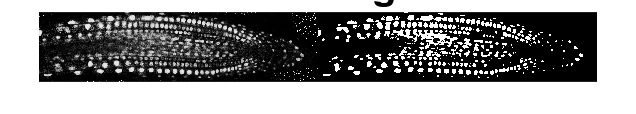

%% read image origin, StackNinja1.bmp image
img = imread("StackNinja1.bmp");

%% convert RGB to HSV 
hsvimg = rgb2hsv(img);

% Extract out the Hue of the image 
hImage = hsvimg(:,:,1);


% filtered_img = imdiffusefilt(hImage,'NumberOfIterations',10);


% Compute Otsu's threshold value
threshold = graythresh(hImage);

% Convert grayscale image to binary using Otsu's threshold value
binaryImg = imbinarize(hImage, threshold);


% Apply median filter with 3x3 neighborhood
filtered_img = medfilt2(binaryImg, [3, 3]);

% 
% greenRange = [0.2, 0.4];
% lowerBound = [greenRange(1), 0.2, 0.2];
% upperBound = [greenRange(2), 1,1];
% 
% % Threshold image to only keep pixels within green range
% greenMask = (hsvImg(:,:,1) >= lowerBound(1)) & (hsvImg(:,:,1) <= upperBound(1)) & ...
%             (hsvImg(:,:,2) >= lowerBound(2)) & (hsvImg(:,:,2) <= upperBound(2)) & ...
%             (hsvImg(:,:,3) >= lowerBound(3)) & (hsvImg(:,:,3) <= upperBound(3));


% Display the hue image.
figure;
imshowpair(hImage,filtered_img,'montage');
title('Hue Image', 'FontSize', 15);








%% Extract the individual red, green, and blue color channels.
% redChannel = img(:, :, 1); % Red Channel
% greenChannel = img(:, :, 2); % Green Channel
% blueChannel = img(:, :, 3); % Blue Channel
% 
% % Greeness
% GreenPic = (greenChannel -(redChannel+blueChannel)/2);
% figure(1);
% imshow(img);
% title('original', 'FontSize', 10);
% imshow(GreenPic);
% title('greenness', 'FontSize', 10);


